clear all;
clc;

u = [4, 3;
     5, 2;
     2, 3;
     3, 4;
     -1 3;
     1, 5;
     6, 2;
     7, 6
    ];
y = [0.3;0.8;-0.05;0.1;-0.8;-0.5;0.5;0.65];
N = length(u(:,1))

N = 8

Phi = [u, ones(N,1)];
theta_hat = Phi\y;
y_pred = Phi*theta_hat

y_pred =     0.2877
    0.5629
   -0.1128
    0.0124
   -0.7136
   -0.4631
    0.7632
    0.6633


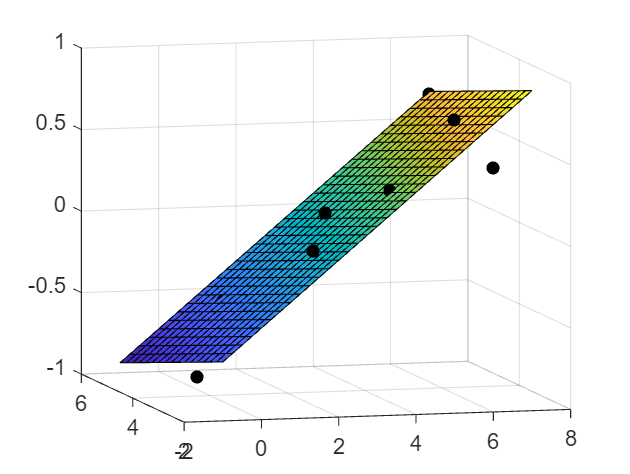

figure
scatter3(u(:,1),u(:,2),y, 'k','o','filled')
hold on
u1t = -1:0.25:7;
u2t = 2:0.25:6;
[U1,U2] = meshgrid(u1t, u2t);
Yt = theta_hat(3) + theta_hat(1)*U1 + theta_hat(2)*U2;
surf(U1,U2,Yt)
hold off

## Polynomial Regression

u1 = u(:,1);
u2 = u(:,2);
u1sq = u1^2;
u2sq = u2^2;
